clear

filename= "/Volumes/azeng/microscopy data/2024_01_17_GEM_timecourse/correct delay/thunderstorm_output/2024_01_17_T66_264_I2_3.nd2.csv"

filename = "/Volumes/azeng/microscopy data/2024_01_17_GEM_timecourse/correct delay/thunderstorm_output/2024_01_17_T66_264_I2_3.nd2.csv"


fileID = fopen(filename, 'r');

formatSpec = '%f%f%f%f%f%f%f%f%f%[^\n\r]';
%basename=files(q).name;
delimiter = ',';
startRow = 2;

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string', 'EmptyValue', NaN, 'HeaderLines' ,startRow-1, 'ReturnOnError', false, 'EndOfLine', '\r\n');
fclose(fileID);
for i=1:9
Poolfoundspots(:,i)= dataArray{i};
end
%%the collumns are {'id','frame','xnm','ynm','sigmanm','intensityphoton','offsetphoton','bkgstdphoton','uncertainty_xynm'});
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

%% 


%-----------------tracking---------
%parameter tracking
Diffcoef=4; %estimate of the maximum distance that a particle would move in a single time interval
Gap=5; %number of time steps that a particle can be 'lost' and then recovered again
good=15; %filter tracks smaller than XYZ timeoints

%parameter MSD fits
thresholdlin=50; %this is the threshold for the linear fit 
thresholdconf=100; %tthreshold for the loglog fit
N_DIM=2;

TIME_UNITS = 's';
%open one of the timing file (should all be the same)
Time2=xlsread(cat(2,'1.tif','_timingms2.xls')); 
dT=round(mean(diff(Time2)))/1000; %dT in seconds usefull for velocities estimation
T=(0:size(Time2,1)-1)';
Time=dT*T; % in seconds

xyspacings=0.11;
SPACE_UNITS = 'µm';  


X=zeros(size(Poolfoundspots,1),4);
X(:,4)=Poolfoundspots(:,2);
X(:,1:2)=Poolfoundspots(:,3:4)./92;%nm to pixel conversion
X(:,5)=Poolfoundspots(:,6);%intensity
X(:,6)=Poolfoundspots(:,5);%offset
X(:,7)=Poolfoundspots(:,7);%sigma
X(:,8)=Poolfoundspots(:,9);%uncertainty

param = struct('mem',Gap,'dim',3,'good',good,'quiet',0);
tracks = track2(X,Diffcoef,param); %modified track to get (intensity, offset, sigma1, uncertainty)  

50 of995 done.  Tracking84 particles316 tracks total
100 of995 done.  Tracking89 particles352 tracks total
150 of995 done.  Tracking77 particles332 tracks total
200 of995 done.  Tracking80 particles319 tracks total
250 of995 done.  Tracking93 particles350 tracks total
300 of995 done.  Tracking93 particles365 tracks total
350 of995 done.  Tracking94 particles382 tracks total
400 of995 done.  Tracking105 particles373 tracks total
450 of995 done.  Tracking113 particles376 tracks total
500 of995 done.  Tracking130 particles419 tracks total
550 of995 done.  Tracking118 particles381 tracks total
600 of995 done.  Tracking87 particles367 tracks total
650 of995 done.  Tracking96 particles373 tracks total
700 of995 done.  Tracking92 particles374 tracks total
750 of995 done.  Tracking110 particles375 tracks total
800 of995 done.  Tracking88 particles394 tracks total
850 of995 done.  Tracking118 particles370 tracks total
900 of995 done.  Tracking95 particles355 tracks total
950 of995 done.  Tracki


%make a cell array with the tracks compatible with MSD analyser 
%with the real timing in sec and the spacings ok

ntracks=tracks(size(tracks,1),9);

% put tracks into
%Cells of MSD analyzer. %also calculate a mean motion of each track t
Mean_motion=cell(ntracks,1);
tracksCell=cell(ntracks, 1);
tracksInt=cell(ntracks, 1);

parfor j=1:ntracks
Temp=tracks(find(tracks(:,9)==j),1:9); 
%get mean motion
T=diff(Temp)*xyspacings;
Mean_motion{j,1}=mean(abs(mean(T(:,2:3))));
%if Mean_motion(j,1)>motionthres
tracksCell{j,1}(:,1)=Time(Temp(:,4)); %put the real time 
tracksCell{j,1}(:,2:3)=Temp(:,1:2)*xyspacings; %this is for 2D
tracksInt{j,1}(:,1)=Time(Temp(:,4)); 
tracksInt{j,1}(:,2:3)=Temp(:,1:2)*xyspacings; %remark z spacings need if 3D 
tracksInt{j,1}(:,4)=zeros(size(Temp,1),1);
tracksInt{j,1}(:,5:8)=Temp(:,5:8)*xyspacings;
end


ma = msdanalyzer(N_DIM, SPACE_UNITS, TIME_UNITS);
%passtracks to msd analyzer
ma = ma.addAll(tracksCell);


ma= ma.fitLogLogMSD(0.5)

Computing MSD of 1276 tracks...  1Done.
Fitting 1276 curves of log(MSD) = f(log(t)), taking only the first 50% of each curve... Done.


ma =   msdanalyzer with properties:

      TOLERANCE: 12
         tracks: {1276×1 cell}
          n_dim: 2
    space_units: 'µm'
     time_units: 's'
            msd: {1276×1 cell}
          vcorr: []
           lfit: []
      loglogfit: [1×1 struct]
          drift: []


ma.loglogfit

ans = struct with fields:
        alpha: [1276×1 double]
        gamma: [1276×1 double]
        r2fit: [1276×1 double]
    alpha_lci: [1276×1 double]
    alpha_uci: [1276×1 double]


r2fits = ma.loglogfit.r2fit;
alphas1 = ma.loglogfit.alpha;

% Add a new column with values from 1 to the length of the vector
newColumn = (1:length(alphas1)).';

% Concatenate the new column to the original data
alphas2 = [newColumn, alphas1];

% Remove bad fits
% Set filtering parameters
R2LIMIT = 0.8;
alphasLIMIT = 0.5;

bad_fits = r2fits < R2LIMIT & alphas1 < alphasLIMIT;
fprintf('Keeping %d fits (R2 > %.2f).\n', sum(~bad_fits), R2LIMIT);

Keeping 756 fits (R2 > 0.80).


alphas = alphas2(~bad_fits, :);

% Extract the effective diffusive coefficients
diffCoefficients = alphas(:,2)/2/ma.n_dim

diffCoefficients =     0.1391
    0.1305
    0.1531
    0.2808
    0.1633
    0.2033
    0.1929
    0.2532
    0.1949
    0.2042


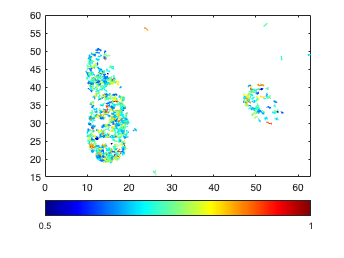


trajectories= ma.tracks;
%filter trajectories based on the index of filtered alphas
filterIndex = ismember(1:length(trajectories), alphas);

% Apply the filter to the trajectories cell array
filteredTrajectories = trajectories(filterIndex);

% Use MATLAB's built-in 'parula' colormap
customCMap = jet(256);

% Set the minimum and maximum values for diffusivity
minDiffusivity = 0.5;
maxDiffusivity = 1;

% Rescale the diffusivity values to the range [0, 1]
normalizedDiffCoefficients = rescale(diffCoefficients, minDiffusivity, maxDiffusivity);

% Map the normalized diffusivity values to colormap indices
colorIndices = round(interp1(linspace(minDiffusivity, maxDiffusivity, 256), 1:256, normalizedDiffCoefficients));

% Plot trajectories with different colors based on diffusivity
figure;

for i = 1:length(filteredTrajectories)
    % Get the corresponding color index for the current trajectory
    colorIndex = colorIndices(i);

    % Plot the trajectory with the selected color
    graphing = plot(filteredTrajectories{i}(:, 2), filteredTrajectories{i}(:, 3), 'Color', customCMap(colorIndex, :), 'LineWidth', 0.25);
    hold on;
end

colormap(customCMap);

% Create a colorbar
c = colorbar('Location', 'southoutside');
caxis([minDiffusivity, maxDiffusivity]);
c.Ticks = [minDiffusivity, maxDiffusivity];

% Set the linewidth of the colorbar
c.LineWidth = 0.25; % Set the desired linewidth
c.FontName = 'Arial';


% Other settings (title, axis limits, etc.) remain the same

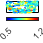

%change title 
%title('36', 'FontWeight', 'normal', 'FontName', 'Arial');

% Remove the default colorbar
delete(findall(gcf, 'Type', 'ColorBar'));

% Create a colorbar
c = colorbar('Location', 'southoutside');

caxis([0.5, 1.2]);
c.Ticks = [0.5, 1.2];

% Set the linewidth of the colorbar
c.LineWidth = 0.25; % Set the desired linewidth
c.FontName = 'Arial';

% Remove x-axis ticks and labels
set(gca, 'XTick', []);

% Remove y-axis ticks and labels
set(gca, 'YTick', []);

% Set custom axis limit s
xlim([10, 20]); % Set the desired x-axis limits
ylim([20,30]); % Set the desired y-axis limits

ax.XColor = 'k'; % Set the X-axis color to black
ax.YColor = 'k'; % Set the Y-axis color to black



ax = gca;
ax.LineWidth = 0.5; % Set the desired linewidth

%set(gcf, 'PaperPosition', [0 0 1.1 1.5]); %Position the plot further to the left and down. Extend the plot to fill entire paper.
%set(gcf, 'PaperSize', [1.1 1.5]); %Keep the same paper size
%aveas(gcf, 'test', 'pdf')


%save image
x_width=0.6 ;y_width=0.6

y_width = 0.6000

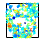

set(gcf, 'Units', 'inches', 'Position', [0, 0, x_width, y_width]);

%delete colorbar
delete(findall(gcf, 'Type', 'ColorBar'));

% Save the figure as a PDF without white space
set(gcf, 'PaperUnits', 'inches', 'PaperPositionMode', 'auto');
%saveas(gcf, 'T60_INK.png', -1200);


print(gcf,'264_T66_INK.pdf','-dpdf','-r1200');